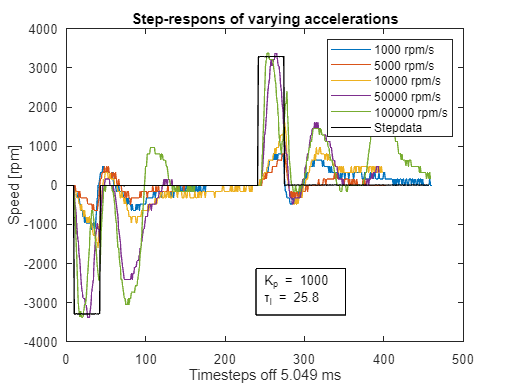

clear
close all
clc
filedir = '';%Filepath
csvfiles = dir(fullfile(filedir, '*.csv'));%Get files
nfiles = length(csvfiles);%Number of files

%Remeber the files has to be in the correct order, inside the folder.
start_steps = zeros(10,1); %Used to make start line
%Names for the legend
names = ["1000 rpm/s", "5000 rpm/s", "10000 rpm/s", "50000 rpm/s", "100000 rpm/s", "Stepdata"];
%textbox on graph
annotation_txt = ["K_p = 1000","τ_I = 25.8"];
for i = 1:nfiles
    csvfile = fullfile(filedir, csvfiles(i).name);
    data = readmatrix(csvfile);
    
    step_data = data(11:end,2); %Stepdata
    %remove first spike and move to same start location
    step1data_start = find(step_data < 0,1);
    sdata_reviewed_1 = [start_steps;step_data(step1data_start:end)]; %stepdata reviewed first step
    
    %remove second spike
    step2data_start = find(sdata_reviewed_1 > 1,1);
    sdata_reviewed_2 = [sdata_reviewed_1(1:step2data_start-5);sdata_reviewed_1(step2data_start:end)];%stepdata reviewed second step
    
    %x_axis for step
    x_axis = (0:length(sdata_reviewed_2)-1);

    %motordata
    motor_data = data(11:end,3);
    motordata_start = find(motor_data < 0);
    %Moving all data to start of graph
    mdata_reviewed = [start_steps;motor_data(motordata_start:end)];
    
    %x_axis for the motor data that match the lengh of the array
    motorx = (0:length(mdata_reviewed)-1);
    

    %plot(x_axis,sdata_reviewed_2)
    plot(motorx,mdata_reviewed)
    hold on

end
plot(x_axis,sdata_reviewed_2,"black")
legend(names);
xlabel("Timesteps off 5.049 ms")
ylabel("Speed [rpm]")
title("Step-respons of varying accelerations")
annotation('textbox', [0.5, 0.2, 0.1, 0.1], 'String', annotation_txt)